# Tutorial 1 - Introduction to Matlab

In this tutorial we will go through some of the basics in Matlab. The live-script offers a nice way to go through everything interactively (similar to the Jupyter notebook in Python). Thus there will be some cells that you have to evaluate yourself and then can comment after what you see.

Before starting, make sure you have the following files from Canvas, both placed within the Tutorial01_Intro directory:

- example_ctd.mat

- transect.m

More instructions regarding the folders will be in "The Working Direcory" section below. Additonally you should have the following toolboxes installed:

- Climate Data Toolbox ( [https://www.mathworks.com/matlabcentral/fileexchange/70338-climate-data-toolbox-for-matlab](https://www.mathworks.com/matlabcentral/fileexchange/70338-climate-data-toolbox-for-matlab) )

**Add toolbox to Matlab search path**

I find it best to store all toolboxes in one separate folder, as they will most likely not be project dependent. You have to add this folder to the Matlab search path so that Matlab can find these functions when called. This can be done either by manually adding the Path *HOME > ENVIRONMENT > Set Path * or by adding the following command at the top of your script: *addpath(genpath('yourpath'))*

Throughout the tutorial, key tasks are indicated by lines that start with 2 exclaimation marks. See below for an example:

**!! Q0** - *Look for tasks like these! There are 9 in this tutorial.*

Note that this tutorial is optional, but for future tutorials, we will check that these tasks have been completed for marking.

## The Working Directory 

Once you start a project you will be dealing with a number of data files and Matlab scripts. These scripts contain a list of instructions that you want Matlab to perform. It is important to keep all your files organised. One way is to keep all your files in a single directory for each lab.

- Make a folder called **CVD_Tutorials**

- Within  the **CVD_Tutorials **directory, create another directory called **Tutorial01_Intro**.

- For this lab you will need the dataset *example_ctd.mat* and the script *transect.m *(from the Climate Data Toolbox for Matlab). You should have installed the toolbox already, but the files are also on the Canvas course website and you can put them into your **Tutorial01_Intro **folder.

- In Matlab set your Current folder to the **CVD_Tutorials/Tutorial01_Intro ** folder. This ensures that Matlab can find all the necessary files. Alternatively, you can also use the unix commands, i.e. *cd yourpath/Matlab_Tutorials/MatlabIntro, *in the command line.

## Using help

Matlab has a very good help function. If you want specific information on a certain functions just type help *functionname. *Go ahead and evaluate the following cell by using *CTR-ENTER*

help mean

 mean   Average or mean value.
    S = mean(X) is the mean value of the elements in X if X is a vector. 
    For matrices, S is a row vector containing the mean value of each 
    column. 
    For N-D arrays, S is the mean value of the elements along the first 
    array dimension whose size does not equal 1.
 
    mean(X,'all') is the mean of all elements in X.
 
    mean(X,DIM) takes the mean along the dimension DIM of X.
 
    mean(X,VECDIM) operates on the dimensions specified in the vector 
    VECDIM. For example, mean(X,[1 2]) operates on the elements contained
    in the first and second dimensions of X.
 
    S = mean(...,TYPE) specifies the type in which the mean is performed, 
    and the type of S. Available options are:
 
    'double'    -  S has class double for any input X
    'native'    -  S has the same class as X
    'default'   -  If X is floating p

If you want to open a parate window, with the full documentation:

%doc mean

## Using Matlab as a calculator

Just run the following lines and see what happens. Alternatively, you could copy the code into the Command Window.

1+1

ans = 2

2^3+10*(5-3)-1/2

ans = 27.5000

(sqrt(9)^2/9)

ans = 1

2*pi*10

ans = 62.8319

## Types of variable 

A **vector** is a list of numbers. An **array** (or **matrix**) is a multidimensional tables of numbers. **Constants** are pre-defined variables that cannot be changed (e.g. pi), but BE CAREFUL you can overwrite these by e.g. defining a variable pi=2. Then you first have to delete the variable (using *clear variablename)* before you can use the constant again. **Strings** are a list of characters.

Variables can be defined by using any name you want:

C = 10

C = 10

cat = 20.3

cat = 20.3000

filename = 'data.mat'

filename = 'data.mat'

You can perform mathematical operations with your variables, and if desired save into a new variable:

D = C*cat

D = 203

C*cat

ans = 203

Variables don't have to be single numbers, they can be vectors (1-D arrays). For example: the monthly average temperature in your office in 2016:

temperature = [16 16.5 17.8 18.3 20 20.4 21.1 21.1 20.3 19.5 18.2,17.5]

temperature =    16.0000   16.5000   17.8000   18.3000   20.0000   20.4000   21.1000   21.1000   20.3000   19.5000   18.2000   17.5000


This creates a 1x12 array. What happens if you you put *'* at the of the command?

Also check out what happens if you put *; * at the end of the command.

temperature = [16 16.5 17.8 18.3 20 20.4 21.1 21.1 20.3 19.5 18.2]'

temperature =    16.0000
   16.5000
   17.8000
   18.3000
   20.0000
   20.4000
   21.1000
   21.1000
   20.3000
   19.5000



temperature = [16 16.5 17.8 18.3 20 20.4 21.1 21.1 20.3 19.5 18.2];

Variables can also be arrays (e.g. temperature each month in your office during 2016,2017 and 2018:

temp2016_2018= [16.5000 17.5 18.3 18.8 20.5 20.4 21.6 21.1 20.8 19.5 18.2 18.1;...
16.5 17.0 18.8 18.3 20.5 20.9 22.1 22.1 20.3 20.0 18.7 17.6;...
16 16.5 17.8 18.3 20 20.4 21.1 21.1 20.3 19.5 18.2 17.1];

% check out the variable detailsq
whos temp2016_2018

  Name               Size            Bytes  Class     Attributes

  temp2016_2018      3x12              288  double              



By using *who variablename * you can check the format of your varibale. As you see, we created an 3x12 array, 12 values for each of the three years. You can use *... *to continue a command in the next line. The semicolon in the brackets tells Matlab to start a new row.

## How to manipulate and work with variables

To display the temperature for November 2016:

temp2016_2018(1,11)

ans = 18.2000

**!! Q1 **-* In the cell below, please write the code to display the temperature for March 2017*

% Add your code here.
% row is first, then columns
temp2016_2018(2,3)

ans = 18.8000

You can do arithmetic on vectors as well. If the office thermomenter is biased and showed temperatures too cold by 0.5°C, you can add an offset to all temperatures:

temp2016_2018+0.5

ans =    17.0000   18.0000   18.8000   19.3000   21.0000   20.9000   22.1000   21.6000   21.3000   20.0000   18.7000   18.6000
   17.0000   17.5000   19.3000   18.8000   21.0000   21.4000   22.6000   22.6000   20.8000   20.5000   19.2000   18.1000
   16.5000   17.0000   18.3000   18.8000   20.5000   20.9000   21.6000   21.6000   20.8000   20.0000   18.7000   17.6000


You can select all records in a given row or column by using the colon. Type the code for displaying: **1)** all temperatures for 2016 and** 2)** all temperatures for July

To get subsets of the data you also use the colon, e.g. the first six months of 2017:

temp2016_2018(2,1:6)

ans =    16.5000   17.0000   18.8000   18.3000   20.5000   20.9000


**!! Q2 -** *Enter the code to display temperatures:*

- All temperatures in 2016

- All July temperatures

% Display all temperatures in 2016
temp2016_2018(1,:)

ans =    16.5000   17.5000   18.3000   18.8000   20.5000   20.4000   21.6000   21.1000   20.8000   19.5000   18.2000   18.1000


% Display all July temperatures
temp2016_2018(1:3, 6)

ans =    20.4000
   20.9000
   20.4000


To get subsets of the data, you use the colon. For example, the first six months of 2017 are retrieved as follows:

temp2016_2018(2,1:6)

ans =    16.5000   17.0000   18.8000   18.3000   20.5000   20.9000


**!! Q3 -** *Enter the code to display temperatures for March and April of 2016 and 2017:*

% Place your code here:
temp2016_2018(1:2,3:4)

ans =    18.3000   18.8000
   18.8000   18.3000


## Using functions

Matlab includes thousands of pre-defined functions, som eif which you have already used (e.g. **whos, sqrt**). Another example is the *mean *function.

**!! Q4 -** *Evaluate the following cell and describe the different outcomes.*

mean(temp2016_2018) % the average temp of every month across the three years

ans =    16.3333   17.0000   18.3000   18.4667   20.3333   20.5667   21.6000   21.4333   20.4667   19.6667   18.3667   17.6000


mean(temp2016_2018,1) % average temp of the month across the three years, 1 indicates all data

ans =    16.3333   17.0000   18.3000   18.4667   20.3333   20.5667   21.6000   21.4333   20.4667   19.6667   18.3667   17.6000


mean(temp2016_2018,2) % average temp of each year, 2 indicates all rows

ans =    19.2750
   19.4000
   18.8583


mean(temp2016_2018(:)) %average temp of all the values

ans = 19.1778

**Answer:**

**!! Q5 **- *Write code to find the mean Jan-Feb-March temperature for 2018.*

% Place your code here:
temp2016_2018(3,1:3)

ans =    16.0000   16.5000   17.8000


mean(temp2016_2018(3,1:3))

ans = 16.7667

Also take a look at other functions, e.g. **max,min,std** Remember you can always use the *help *command to learn how to use a certain function.

## First Data Example: Working with CTD Casts

We will use the example CTD dataset which includes 95 CTD casts. While this is a simple dataset, there are some challanges to it:

- As the ocean is not flat, each cast usually has a different length, i.e. a different number of data points. Thus it is not straight forward to put all profiles into a matrix.

- The data points might be at not exactly the same depth levels for each profiles

Load the data set example_ctd.mat and use *whos *to check which variables have been loaded.

clear all
load example_ctd.mat
whos

  Name      Size            Bytes  Class     Attributes

  P         1x95            24392  cell                
  S         1x95            24392  cell                
  T         1x95            24392  cell                
  bed       1x95              760  double              
  x         1x95              760  double              



As you can see there are three **cell** objects, which represent pressure (P), salinity (S) and temperature (T). These cells contain our 95 casts and allow for them to have different sizes. You can access a cell by using curly brackets.

cast1 = P{1};
cast2 = P{70};
whos cast1 cast2

  Name        Size            Bytes  Class     Attributes

  cast1      17x1               136  double              
  cast2      20x1               160  double              



Another way to store heterogenous data are **structs. **Here is how you would create one called CTD:

clear CTD
CTD(1).temp = T{1};
CTD(1).sal = S{1};
CTD(1).pres = P{1};

CTD = struct with fields:
    temp: [17×1 double]
     sal: [17×1 double]
    pres: [17×1 double]


CTD

Use a loop to go through all the 95 casts.

for i = 1:length(S)
    CTD(i).temp = T{i};
    CTD(i).sal = S{i};
    CTD(i).pres = P{i};
end
CTD

CTD = 1×95 struct array with fields:
    temp
    sal
    pres


Access the first profile in the struct:

CTD(1)

ans = struct with fields:
    temp: [17×1 double]
     sal: [17×1 double]
    pres: [17×1 double]


## Plotting CTD Profiles

Now lets you do some plotting; we will stick to the cell format for now. 

**!! Q6** - *Pick out two temperature or salinity profiles and plot them, and/or try to plot them all with a loop. Use the functions xlabel, ylabel and title to label the graph (Use help to understand how it is done). Uncomment the additional commands and see what happens. Also try out some plotting options and replace '-' with 'x', '--', 'o', 'r'. Modifiy the linewidth by adding 'linewidth',2*

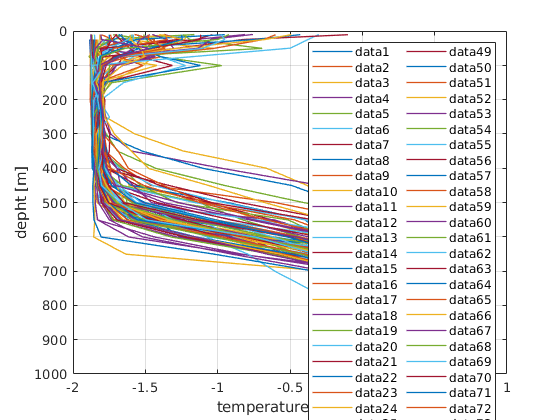

figure(1),clf % clears the figures

for i = 1:length(S)
plot(T{i},P{i},'-','linewidth',1)
hold on
end

axis ij % reverses y-axis
grid on % turns grid on
xlabel('temperature [degC]')
ylabel('depht [m]')

legend('location','east','NumColumns',2)

**!! Q7** - *What can the temperature profiles tell us? Do you think this data has been collected from highor low latitudes?*

**Answer:** These temperature profiles tell us that the water is much warmer at the surface, then cools and become warmer again at the botton, My guess is these are taken at lower latitudes

## T-S Diagram

In oceanography CTD data is often plotted in a TS-diagram, which allows us to identify watermasses. For this salinity is commonly plotted on the x-axis and temperature on the y-axis.

**!! Q8 -** *Try plotting a T-S diagram for all profiles of the CTD data. Hint: plot one data point for each CTD cast and depth level. Don't forget the hold-on domain and use "." as a marker.*

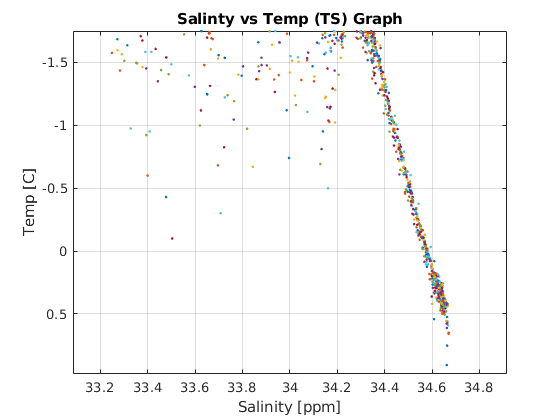

% Place your code in here. Additional hint: you can try plot() or scatter()
figure(1),clf
for i = 1:length(S)
plot(S{i},T{i},'.','linewidth',1)
hold on
end
axis ij % reverses y-axis
grid on % turns grid on
xlabel('Salinity [ppm]')
ylabel('Temp [C]')
title('Salinty vs Temp (TS) Graph')

## Hydrographic section

Another important part is plotting all stations as a hydrographic section, which represents a slice through the ocean. For this some data manipulation has to be done (we mentioned the problems earlier), since Matlab requests a 2D matrix to do these surface plots. 

If you are already a little bit advanced in Matlab try to do the steps yourself:

- Interpolate each profile (with a loop) on the same depth levels (using *interp1) * 

- Create and empty matrix using the function *NaN.* It has to have dimensions *number of profiles *  length of longest cast.*

If you don't feel comfortable doing this check out this link:

[http://www.chadagreene.com/CDT/transect_documentation.html](http://www.chadagreene.com/CDT/transect_documentation.html) 

This functions saves you all the work and allows you to plot a fancy section fairly easy ;-) And it allows to put our data in the way it is. Below is the simplest way of using the function.

Explore different options that are described on the link, make it YOUR section and again label the axes of the graph and add a colorbar. 

**!! Q9** - *Following the instructions above, plot a hydrographic section using either the transects() function or your own code. Describe below what you see in the graph.*

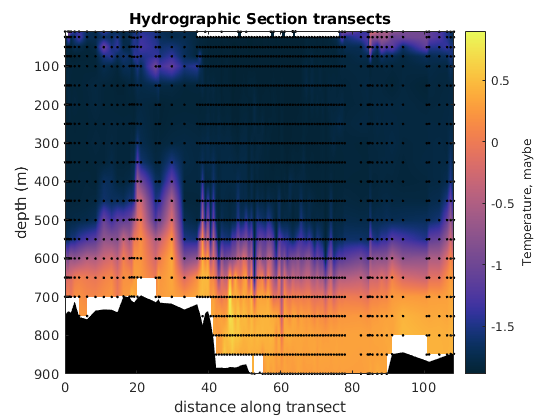

% Place your code here:
figure(1),clf
transect(x,P,T,'bed',bed)
colorbar
h = colorbar;
cmocean thermal 
set(get(h,'label'),'string','Temperature, maybe');
xlabel('distance along transect')
ylabel('depth (m)')
title('Hydrographic Section transects')

% in this we see the distane along the transect, the seabed, and the
% temperature in the colorbar


## Doing the same thing but with my own code

Totally just skipped it, a function already exists

If you are already a little bit advanced in Matlab try to do the steps yourself:

- Interpolate each profile (with a loop) on the same depth levels (using *interp1) * 

- Create and empty matrix using the function *NaN.* It has to have dimensions *number of profiles *  length of longest cast.*

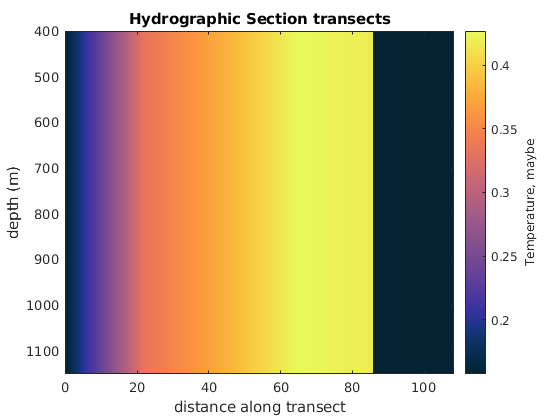

% interpolate through each profile with loop on same depth level
Pmax = max(cellfun(@max,P));
Pmin = min(cellfun(@max,P));

di = linspace(Pmin,Pmax,1000);
for i=1:length(S)
   P_loop = P{i};
   T_loop = T{i};
   % Vector x contains the sample points, and v contains the corresponding values, v(x). 
   % Vector xq contains the coordinates of the query points
   % x is the horizontal dist, P/pressure the depth, T is the temperature
profile = interp1(P_loop,T_loop,di);
end

Prof_num = 95;
longest_cast = max(x);

%%
figure(2)
imagesc(x,di,profile)
%plot(x,profile_clean)
colorbar
h = colorbar;
cmocean thermal 
set(get(h,'label'),'string','Temperature, maybe');
xlabel('distance along transect')
ylabel('depth (m)')
title('Hydrographic Section transects')

**Answer:**